# **Vision Artificial. GIEC - Sistemas de Vision Artificial. GIC**

# **Práctica 3. Segmentación de Imágenes (II)**

**Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Autor(es): Isaac Marval, Diego Pena**

**Fecha: 30/10/2025**

Este mlx contiene la parte de la práctica 3 relaiconada con la segmentación basada en bordes y el uso de la transformada de Hough para detectar rectas y círculos. Además de la segmentación basada en bordes, también se contempla en este mlx la transformada de Watershed. 

La **entrega **se realizará en el Aula Virtual de la asignatura: Contenidos --> Entregables --> Práctica 3.

**Ejercicios propuestos:**

**1. Transformada Watershed:**

- Cargue la imagen `'circles.png'` umbralízela y realize una segmentación utilizando la transformada de Watershed. ¿Existe sobre-segmentación, es decir, se han segmentado muchos más objetos de los que hay en la imagen? En caso de que exista, intente reducirla (utilizando, por ejemplo, operadores morfológicos).

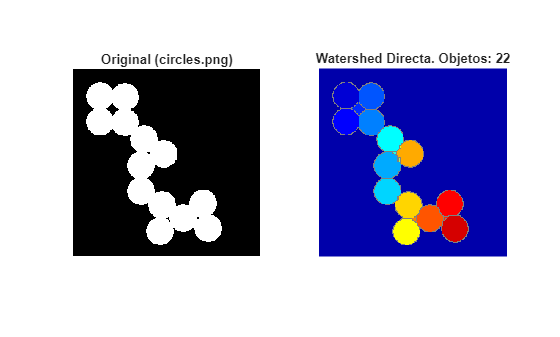

close all; clear all; clc;

imgDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\Imagenes';
pracDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\practica 3';


I = imread(fullfile(imgDir,'circles.png'));
I = im2double(I);

% 1. Convertir y Umbralizar (Lineal No Supervisada)
level = graythresh(I); % Umbral Otsu
bw = imbinarize(I, level);

% 2. Calcular la Transformada de Distancia (DT)
% Se calcula la distancia a los no-objetos (~bw)
D = bwdist(~bw);

% 3. Negar y forzar los no-objetos a -Inf
% Los picos de la DT (centros de los objetos) se convierten en valles.
D = -D; 
D(~bw) = -Inf; % Fuerzar el fondo (no-objetos) a ser los mínimos absolutos

% 4. Aplicar la Transformada Watershed
L = watershed(D);

% 5. Visualizar la Segmentación
rgb = label2rgb(L,'jet',[.5 .5 .5]);
figure('Name','(1) Transformada Watershed Directa','NumberTitle','off');
subplot(1,2,1); imshow(I); title('Original (circles.png)');
subplot(1,2,2); imshow(rgb); title(sprintf('Watershed Directa. Objetos: %d', max(L(:))));


% si existe sobre segmentacion en la imagen, encuentra 22 objetos, podemos
% reducirlo si utlizarmos por ejemplo un cierre, una dialatacion seguida de
% una erosion






**2. Segmentación basada en bordes:**

- Abra la imagen "coins.png".

- Detecte los bordes utilizando el filtro de Canny. Utilice controles deslizantes (*numeric sliders*) para configurar los distintos parámetros y visualice el efecto de las diferentes configuraciones. Comente los efectos sobre los bordes del cambio de cada parámetro.

- Cierre contornos dilatando los bordes obtenidos (*imdilate*). Visualice.

- Rellene los contornos obtenidos.

- Segmente los distintos objetos, etiquetándolos con *bwlabel *y muestre el resultado final.

- Repita los pasos 1 a 5 utilizando la máscara de `'sobel'``y`** compare los resultados (canny - sobel**). Justifique.

- Repita los pasos 1 a 5 y compare los resultados realizando o no la dilatación (paso 3). Justifique.

- Compare los resultados obtenidos al utilizar diferentes elementos estructurantes en la dilatación. Justifique.

- Compare los resultados realizando una dilatación (*imdilate*) o un cierre (*imclose*). Justifique.

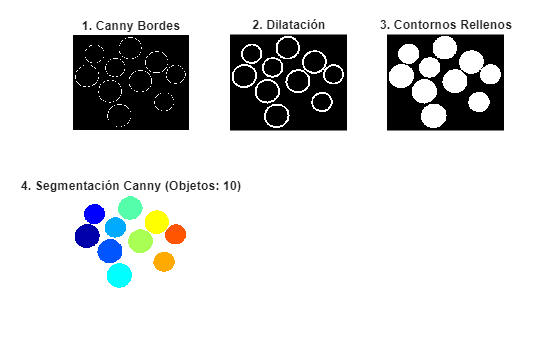




I = imread('coins.png'); 

% 1. Detectar Bordes con Canny (ajuste de parámetros por defecto o fino)
BW_canny = edge(I, 'canny', [0.1 0.4], 1.5); % Ejemplo de parámetros finos

figure('Name','(2) Segmentación Basada en Bordes (Canny)','NumberTitle','off');
subplot(2,3,1); imshow(BW_canny); title('1. Canny Bordes');

% 2. Cerrar Contornos con Dilatación (imdilate)
% Se usa un elemento estructurante (SE) para conectar los bordes fragmentados.
se_dilate = strel('disk', 2); % Disco de radio 2
BW_dilatada = imdilate(BW_canny, se_dilate);
subplot(2,3,2); imshow(BW_dilatada); title('2. Dilatación');

% 3. Rellenar Contornos (Holes)
% Rellena los agujeros (los objetos) dentro de los contornos cerrados.
BW_rellena = imfill(BW_dilatada, 'holes');
subplot(2,3,3); imshow(BW_rellena); title('3. Contornos Rellenos');

% 4. Segmentar y Etiquetar Objetos
% Eliminar el fondo (borde de la imagen) para segmentar solo los objetos internos.
BW_sin_borde = imclearborder(BW_rellena);
[L, num_objetos] = bwlabel(BW_sin_borde);
RGB_seg = label2rgb(L, 'jet', 'w');
subplot(2,3,4); imshow(RGB_seg); title(sprintf('4. Segmentación Canny (Objetos: %d)', num_objetos));

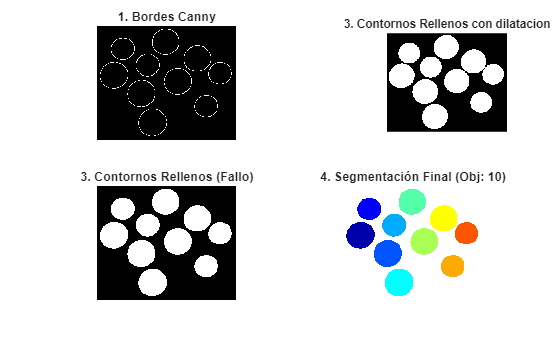

% usamos 3 parametros, el umbral bajo, define el minimo para que un pixel
% sea considerado parte del borde. el umbral alto como borde definido.
% por ultimo el sigma el nivel de suavisado.





% Canny con sin dilatar


I = imread('coins.png'); 
I_gray = I; 

% --- 1. Detectar Bordes con Canny ---
sigma = 1.5;
BW_canny = edge(I_gray, 'canny', [0.1 0.4], sigma); 

% --- 2. Cierre de Contornos (Paso OMITIDO) ---
% La imagen BW_canny pasa directamente al relleno.

% --- 3. Relleno de Contornos (imfill) ---
% Se rellena directamente la imagen de bordes Canny
BW_rellena_sin_dilate = imfill(BW_canny, 'holes');

% --- 4. Segmentación y Etiquetado (bwlabel) ---
BW_sin_borde_sin_dilate = imclearborder(BW_rellena_sin_dilate);
[L_sin_dilate, num_sin_dilate] = bwlabel(BW_sin_borde_sin_dilate);
RGB_seg_sin_dilate = label2rgb(L_sin_dilate, 'jet', 'w');

figure('Name','(2) Segmentación Canny Sin Dilatación','NumberTitle','off');
subplot(2,2,1); imshow(BW_canny); title('1. Bordes Canny');
subplot(2,3,3); imshow(BW_rellena); title('3. Contornos Rellenos con dilatacion');

subplot(2,2,3); imshow(BW_rellena_sin_dilate); title('3. Contornos Rellenos (Fallo)');
subplot(2,2,4); imshow(RGB_seg_sin_dilate); title(sprintf('4. Segmentación Final (Obj: %d)', num_sin_dilate));

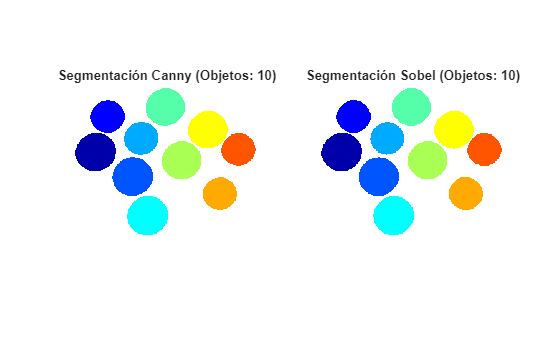



%sobel contra canny
I = imread('coins.png'); 
I_gray = I; 

% Definir el Elemento Estructurante (SE)
se_dilate = strel('disk', 2); 

% ----------------------------------------------------
% --- A. Segmentación Canny (Referencia) ---
sigma = 1.5;
BW_canny = edge(I_gray, 'canny', [0.1 0.4], sigma); 
BW_dilatada_canny = imdilate(BW_canny, se_dilate);
BW_rellena_canny = imfill(BW_dilatada_canny, 'holes');
BW_sin_borde_canny = imclearborder(BW_rellena_canny);
[L_canny, num_canny] = bwlabel(BW_sin_borde_canny);
RGB_seg_canny = label2rgb(L_canny, 'jet', 'w');

% ----------------------------------------------------
% --- B. Segmentación Sobel 
% 1. Detectar Bordes con Sobel
BW_sobel = edge(I_gray, 'sobel'); 

% 2. Cierre de Contornos (Dilatación)
BW_dilatada_sobel = imdilate(BW_sobel, se_dilate);

% 3. Relleno de Contornos (imfill)
BW_rellena_sobel = imfill(BW_dilatada_sobel, 'holes');

% 4. Segmentación y Etiquetado (bwlabel)
BW_sin_borde_sobel = imclearborder(BW_rellena_sobel);
[L_sobel, num_sobel] = bwlabel(BW_sin_borde_sobel);
RGB_seg_sobel = label2rgb(L_sobel, 'jet', 'w');

% ----------------------------------------------------
% --- Comparación Visual ---
figure('Name','(2) Segmentación Canny vs Sobel','NumberTitle','off');
subplot(1,2,1); imshow(RGB_seg_canny); title(sprintf('Segmentación Canny (Objetos: %d)', num_canny));
subplot(1,2,2); imshow(RGB_seg_sobel); title(sprintf('Segmentación Sobel (Objetos: %d)', num_sobel));

% no encontramos ninguna diferencia en este ejemplo.

% canny con sin dilatar


I = imread('coins.png'); 
I_gray = I; 

% --- 1. Detectar Bordes con Canny ---
sigma = 1.5;
BW_canny = edge(I_gray, 'canny', [0.1 0.4], sigma); 


% --- 3. Relleno de Contornos (imfill) ---
% Se rellena directamente la imagen de bordes Canny
BW_rellena_sin_dilate = imfill(BW_canny, 'holes');

% --- 4. Segmentación y Etiquetado (bwlabel) ---
BW_sin_borde_sin_dilate = imclearborder(BW_rellena_sin_dilate);
[L_sin_dilate, num_sin_dilate] = bwlabel(BW_sin_borde_sin_dilate);
RGB_seg_sin_dilate = label2rgb(L_sin_dilate, 'jet', 'w');

figure('Name','(2) Segmentación Canny Sin Dilatación','NumberTitle','off');
subplot(2,2,1); imshow(BW_canny); title('1. Bordes Canny');
subplot(2,3,3); imshow(BW_rellena); title('3. Contornos Rellenos con dilatacion');

subplot(2,2,3); imshow(BW_rellena_sin_dilate); title('3. Contornos Rellenos (Fallo)');
subplot(2,2,4); imshow(RGB_seg_sin_dilate); title(sprintf('4. Segmentación Final (Obj: %d)', num_sin_dilate));

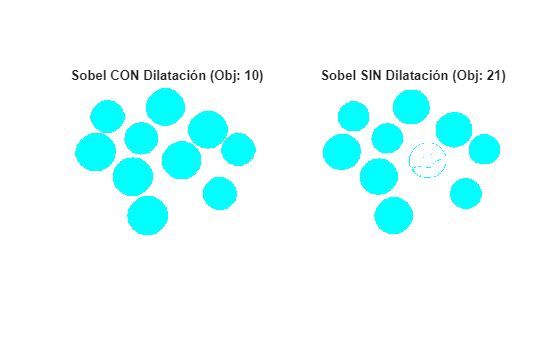


% en este caso como los bordes estan bien definidos desde un principio la
% dilatacion no tiene gran efecto.


%sobel sin dilatacion
I = imread('coins.png'); 
I_gray = I; 

% --- Definición del SE (Necesario para la comparación anterior, pero no usado en este flujo) ---
se_dilate = strel('disk', 2); 

% ----------------------------------------------------
% --- A. Segmentación Sobel CON Dilatación (Referencia Anterior) ---
BW_sobel_con = edge(I_gray, 'sobel'); 
BW_rellena_con = imfill(imdilate(BW_sobel_con, se_dilate), 'holes');
[~, num_con] = bwlabel(imclearborder(BW_rellena_con));
RGB_seg_con = label2rgb(imclearborder(BW_rellena_con), 'jet', 'w');

% ----------------------------------------------------
% --- B. Segmentación Sobel SIN Dilatación ---
% 1. Detectar Bordes con Sobel
BW_sobel_sin = edge(I_gray, 'sobel'); 

% 2. Cierre de Contornos (Paso OMITIDO) 
% La imagen BW_sobel_sin pasa directamente al relleno.

% 3. Relleno de Contornos (imfill)
BW_rellena_sin = imfill(BW_sobel_sin, 'holes');

% 4. Segmentación y Etiquetado (bwlabel)
BW_sin_borde_sin = imclearborder(BW_rellena_sin);
[~, num_sin] = bwlabel(BW_sin_borde_sin);
RGB_seg_sin = label2rgb(BW_sin_borde_sin, 'jet', 'w');

% ----------------------------------------------------
% --- Comparación Visual ---
figure('Name','(2) Comparación Sobel Con vs Sin Dilatación','NumberTitle','off');
subplot(1,2,1); imshow(RGB_seg_con); title(sprintf('Sobel CON Dilatación (Obj: %d)', num_con));
subplot(1,2,2); imshow(RGB_seg_sin); title(sprintf('Sobel SIN Dilatación (Obj: %d)', num_sin));

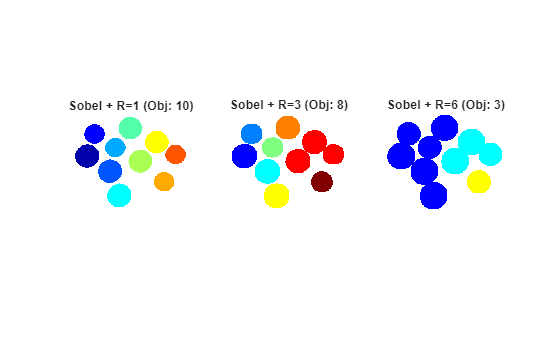

% con sobel si podemos ver que hay diferencia con hacer dialatacion o no. en
% el caso de no hacer dilatacicon una de las monedas no logra encontrar sus
% bordes y da fallos a la hora de encontrar los objetos.






I = imread('coins.png'); 
I_gray = I; 

% 1. Detectar Bordes con Sobel (se mantiene fijo)
BW_sobel = edge(I_gray, 'sobel'); 

% --- Definición de Elementos Estructurantes (SE) ---
se_pequeno = strel('disk', 1); 
se_mediano = strel('disk', 3); 
se_grande = strel('disk', 6); 

% ----------------------------------------------------
% --- Flujo con SE PEQUEÑO (R=1) ---
BW_dilatada_peq = imdilate(BW_sobel, se_pequeno);
BW_seg_peq = imfill(BW_dilatada_peq, 'holes');
BW_sin_borde_peq = imclearborder(BW_seg_peq); % Eliminar borde antes de etiquetar
[L_peq, num_peq] = bwlabel(BW_sin_borde_peq);
RGB_seg_peq = label2rgb(L_peq, 'jet', 'w'); % ¡Generar pseudo-color!

% --- Flujo con SE MEDIANO (R=3) ---
BW_dilatada_med = imdilate(BW_sobel, se_mediano);
BW_seg_med = imfill(BW_dilatada_med, 'holes');
BW_sin_borde_med = imclearborder(BW_seg_med);
[L_med, num_med] = bwlabel(BW_sin_borde_med);
RGB_seg_med = label2rgb(L_med, 'jet', 'w'); % ¡Generar pseudo-color!

% --- Flujo con SE GRANDE (R=6) ---
BW_dilatada_gde = imdilate(BW_sobel, se_grande);
BW_seg_gde = imfill(BW_dilatada_gde, 'holes');
BW_sin_borde_gde = imclearborder(BW_seg_gde);
[L_gde, num_gde] = bwlabel(BW_sin_borde_gde);
RGB_seg_gde = label2rgb(L_gde, 'jet', 'w'); % ¡Generar pseudo-color!

% ----------------------------------------------------

figure('Name','(2) Comparación SE en Dilatación (Sobel) [Pseudo-Color]','NumberTitle','off');

subplot(1,3,1); 
imshow(RGB_seg_peq); % Mostrar la imagen RGB
title(sprintf('Sobel + R=1 (Obj: %d)', num_peq));

subplot(1,3,2); 
imshow(RGB_seg_med); % Mostrar la imagen RGB
title(sprintf('Sobel + R=3 (Obj: %d)', num_med));

subplot(1,3,3); 
imshow(RGB_seg_gde); % Mostrar la imagen RGB
title(sprintf('Sobel + R=6 (Obj: %d)', num_gde));

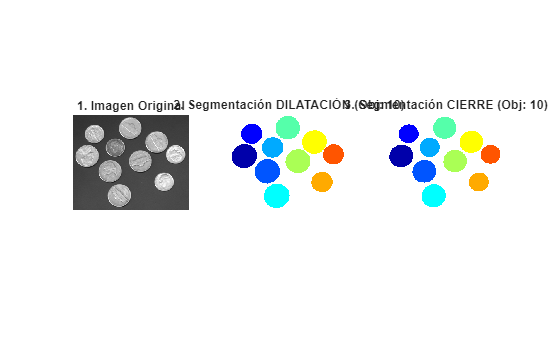


% hay que usar un strel de bajo nivel, si usamos uno muy grande los objetos
% se mezclan.





I = imread('coins.png'); 
I_gray = I; % Imagen original en gris

% 1. Detección de Bordes con Canny (se mantiene fijo)
BW_canny = edge(I_gray, 'canny', [0.1 0.4], 1.5); 
se_morph = strel('disk', 2); 

% ----------------------------------------------------
% --- A. Segmentación con DILATACIÓN (imdilate) ---
BW_dilatada = imdilate(BW_canny, se_morph);
BW_rellena_dilatada = imfill(BW_dilatada, 'holes');
BW_sin_borde_dilatada = imclearborder(BW_rellena_dilatada);
[L_dilatada, num_dilatada] = bwlabel(BW_sin_borde_dilatada);
% Resultado Pseudo-Color
RGB_seg_dilatada = label2rgb(L_dilatada, 'jet', 'w');

% ----------------------------------------------------
% --- B. Segmentación con CIERRE (imclose) ---
BW_cierre = imclose(BW_canny, se_morph);
BW_rellena_cierre = imfill(BW_cierre, 'holes');
BW_sin_borde_cierre = imclearborder(BW_rellena_cierre);
[L_cierre, num_cierre] = bwlabel(BW_sin_borde_cierre);
% Resultado Pseudo-Color
RGB_seg_cierre = label2rgb(L_cierre, 'jet', 'w');

% ----------------------------------------------------
% --- Visualización para Comparación Directa ---

figure('Name','(2) Comparación Segmentación vs Original','NumberTitle','off');

% 1. Imagen Original
subplot(1,3,1); 
imshow(I_gray); 
title('1. Imagen Original');

% 2. Resultado con Dilatación
subplot(1,3,2); 
imshow(RGB_seg_dilatada); 
title(sprintf('2. Segmentación DILATACIÓN (Obj: %d)', num_dilatada));

% 3. Resultado con Cierre
subplot(1,3,3); 
imshow(RGB_seg_cierre); 
title(sprintf('3. Segmentación CIERRE (Obj: %d)', num_cierre));


%% es mejor usar en este caso la dilatacion solo, porque hacer un cierre, modifica mucho mas el tamaño de cada moneda y está mas cerca de dar fallos.

**3. Detección de rectas utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, pinte las 7 rectas más largas de la imagen **'despacho1.jpg'**. 

- Verifique la función de los parámetros 'FillGap' y 'MinLength' modificando su valor (por ejemplo, mediante *sliders*) y visualizando el resultado. Comente su efecto sobre las líneas detectadas.

- Calcule el número de picos `length(P)` y el número de líneas `length(lines)` obtenidas. ¿Son iguales o diferentes? ¿por qué?

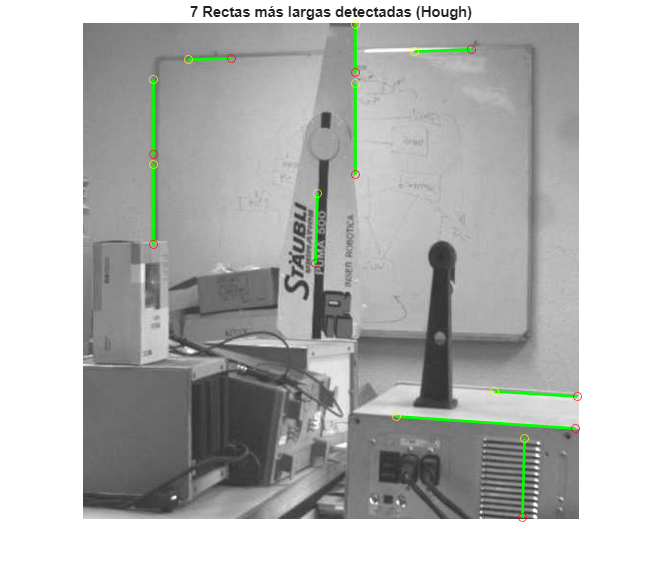



imgDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\Imagenes';
pracDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\practica 3';


I = imread(fullfile(imgDir,'despacho1.jpg'));
BW = edge(rgb2gray(I), 'canny'); % Detectar bordes primero

% 1. Transformada de Hough
[H, theta, rho] = hough(BW);

% 2. Encontrar los picos (puntos con más votos)
P = houghpeaks(H, 7, 'threshold', ceil(0.3*max(H(:)))); % 7 picos (7 rectas más largas)

% 3. Encontrar las líneas (agrupar píxeles en líneas)
% Se usan MinLength y FillGap para determinar qué picos forman líneas.
lines = houghlines(BW, theta, rho, P, 'FillGap', 5, 'MinLength', 40);

% 4. Visualizar y pintar las 7 rectas
figure('Name','(3) Transformada de Hough - Rectas','NumberTitle','off');
imshow(I); hold on;
max_len = 0;

for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    
    % Pintar la recta
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');

    % Pintar los extremos
    plot(xy(1,1), xy(1,2), 'o', 'Color', 'yellow');
    plot(xy(2,1), xy(2,2), 'o', 'Color', 'red');
end
title('7 Rectas más largas detectadas (Hough)');
hold off;

%'FillGap' es la cantidad de espacio entre los puntos y 'MinLength' es el
%tamaño minimo de las rectas encontradas.

**4. Detección de círculos utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, localice y pinte el contorno de las células de la imagen **'blood1.tif'** cuyo radio esté entre 7 y 20 píxeles. Si fuera necesario, considere la posibilidad de umbralizar la imagen y/o de invertirla antes de aplicar la transformada.

- Resalte la célula más grande pintándola de un color diferente.

- ¿Cuántas células ha encontrado?

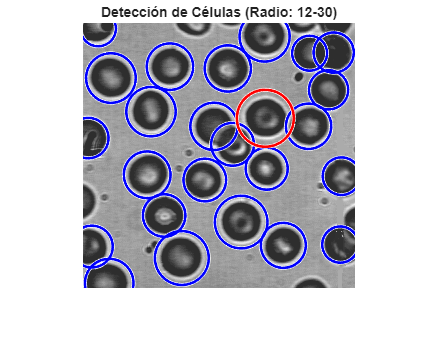


 

imgDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\Imagenes';
pracDir = 'C:\Users\isaac\Documents\GitHub\Vision artificial\Vision-Artificial-isaac-diego\practica 3';


I = imread(fullfile(imgDir,'blood1.tif'));
I_gray = im2gray(I);

% 1. (Opcional) Pre-procesamiento: Invertir y Umbralizar (si es necesario)
% Las células son más brillantes que el fondo en 'blood1.tif'.
% Detectaremos bordes sobre la imagen original.
BW = edge(I_gray, 'canny'); 

% 2. Detección de Círculos (Radios entre 7 y 20 píxeles)
radio_range = [12 30];
[centers, radii] = imfindcircles(BW, radio_range, 'ObjectPolarity', 'bright', 'Sensitivity', 0.9);

% 3. Visualizar los resultados
figure('Name','(4) Transformada de Hough - Círculos (Células)','NumberTitle','off');
imshow(I);
title(sprintf('Detección de Células (Radio: %d-%d)', radio_range(1), radio_range(2)));
hold on;

% 4. Resaltar la célula más grande
[max_radius, max_idx] = max(radii);
centers_max = centers(max_idx,:);
radii_max = radii(max_idx);

% Pintar todas las células (en azul)
viscircles(centers, radii, 'EdgeColor', 'b');

% Pintar la célula más grande (en rojo)
viscircles(centers_max, radii_max, 'EdgeColor', 'r', 'LineWidth', 2); 
hold off;

%hemos encontrado 26 celuludas diferentes.